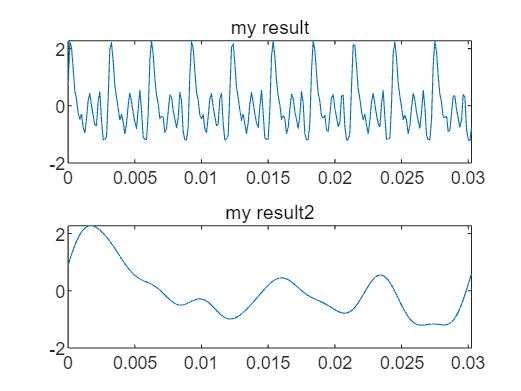

load Guitar.MAT

Fs = 8000;
% figure;
% subplot(1,3,1);
% plot([0:length(realwave)-1]/Fs, realwave);
% title('realwave');
% subplot(1,3,2);
% plot([0:length(wave2proc)-1]/Fs, wave2proc);
% title('wave2proc');

wav = resample(realwave, 10, 1);
len = length(realwave);
res = zeros([len 1]);
for k = 1:10
    res = res + wav((k-1)*len+1:k*len);
end
tmp = res;
res = repmat(res, 10, 1);
res = resample(res, 1, 10);
subplot(2,1,1);
plot([0:len-1]/Fs, res);
title('my result');
res = tmp;
subplot(2,1,2);
plot([0:length(res)-1]/Fs, res);
title('my result2');